# **Image Transmission via OFDM System Utilizing the IEEE 802.11a WLAN Physical Layer Implementation **

clc;
clear all ; 
close all ;

**Project requirements**

% SNR range for BER comparison
snr_range = 0:2:20;
imagepath="C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png";
code_rate=1/3;
const_len=7;
cp_length=16;
fc=5.2^10^9;
fs=20*10^6;
gain=4;
% Initialize BER arrays
ber_zf_16qam = zeros(1, length(snr_range));
ber_w_16qam = zeros(1, length(snr_range));
ber_zf_bpsk = zeros(1, length(snr_range));
ber_w_bpsk = zeros(1, length(snr_range));

**BPSK and 16QAM modulation**

for i = 1:length(snr_range)
    snr = snr_range(i);
    
    % BPSK modulation
    modulation_type = "BPSK";
    [transmitted_signal,constellation,ofdm_symbol_with_cp,Whole_Data] = transmitter(imagepath, code_rate, const_len, modulation_type, cp_length, fc, fs, gain);
    received_signal = simulate_wireless_channel_AWGN(transmitted_signal, snr);
    received_signal = received_signal(1:length(transmitted_signal));
    amplified_signalrcv = LNA(received_signal, 1.01);
    demodsignal = IQ_Demodulation(amplified_signalrcv, fc, fs);
    parallel_data = Serial_To_Parallel(demodsignal);
    WithoutCP = Remove_Cyclic_Prefix(parallel_data, cp_length);
    fftt = FFT_operation(WithoutCP);
    freq_e_ZF = Frequency_Equalizer(fftt, 'ZF', 0,Whole_Data);
    freq_e_W = Frequency_Equalizer(fftt, 'W', snr,Whole_Data);
    % demapped_bits_zf = Symbol_Demapping(freq_e_ZF, modulation_type);
    % demapped_bits_w = Symbol_Demapping(freq_e_W, modulation_type);
    % decoded_bits_zf = FEC_Decoding(demapped_bits_zf, code_rate);
    % decoded_bits_w = FEC_Decoding(demapped_bits_w, code_rate);
    % ber_zf_bpsk(i) = sum(decoded_bits_zf ~= binary_data) / length(binary_data);
    % ber_w_bpsk(i) = sum(decoded_bits_w ~= binary_data) / length(binary_data);
    % 
end

for i = 1:length(snr_range)
    snr = snr_range(i);    
% 16QAM modulation
    modulation_type = "16QAM";
    [transmitted_signal,constellation,ofdm_symbol_with_cp,Whole_Data] = transmitter(imagepath, code_rate, const_len, modulation_type, cp_length, fc, fs, gain);
    received_signal = simulate_wireless_channel_AWGN(transmitted_signal, snr);
    received_signal = received_signal(1:length(transmitted_signal));
    amplified_signalrcv = LNA(received_signal, 1.01);
    demodsignal = IQ_Demodulation(amplified_signalrcv, fc, fs);
    parallel_data = Serial_To_Parallel(demodsignal);
    WithoutCP = Remove_Cyclic_Prefix(parallel_data, cp_length);
    fftt = FFT_operation(WithoutCP);
    freq_e_ZF = Frequency_Equalizer(fftt, 'ZF', 0,Whole_Data);
    freq_e_W = Frequency_Equalizer(fftt, 'W', snr,Whole_Data);
    % demapped_bits_zf = Symbol_Demapping(freq_e_ZF, modulation_type);
    % demapped_bits_w = Symbol_Demapping(freq_e_W, modulation_type);
    % decoded_bits_zf = FEC_Decoding(demapped_bits_zf, code_rate);
    % decoded_bits_w = FEC_Decoding(demapped_bits_w, code_rate);
    % ber_zf_16qam(i) = sum(decoded_bits_zf ~= binary_data) / length(binary_data);
    % ber_w_16qam(i) = sum(decoded_bits_w ~= binary_data) / length(binary_data);
end

**Constellation diagrams for 16QAM**

% Constellation diagrams for 16QAM
modulation_type = "16QAM";
transmitted_signal = transmitter(imagepath, code_rate, const_len, modulation_type, cp_length, fc, fs, gain);
received_signal = simulate_wireless_channel_AWGN(transmitted_signal, 10); % Choose any desired SNR
received_signal = received_signal(1:length(transmitted_signal));
amplified_signalrcv = LNA(received_signal, 1.01);
demodsignal = IQ_Demodulation(amplified_signalrcv, fc, fs);
parallel_data = Serial_To_Parallel(demodsignal);
WithoutCP = Remove_Cyclic_Prefix(parallel_data, cp_length);
fftt = FFT_operation(WithoutCP);
freq_e_ZF = Frequency_Equalizer(fftt, 'ZF', 0);
freq_e_W = Frequency_Equalizer(fftt, 'W', 10);

figure;
scatter(real(freq_e_ZF), imag(freq_e_ZF), 'b.');
title('Constellation Diagram - ZF Equalizer (16QAM)');
xlabel('Real');
ylabel('Imaginary');

figure;
scatter(real(freq_e_W), imag(freq_e_W), 'r.');
title('Constellation Diagram - Wiener Equalizer (16QAM)');
xlabel('Real');
ylabel('Imaginary');

**Testing the Project**

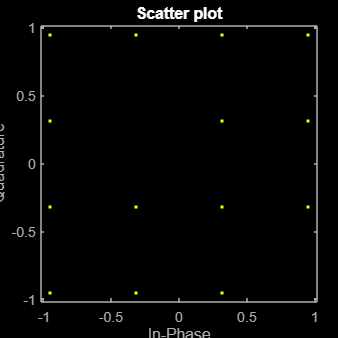


% this part of the code is for testing the project only
% consider ignoring or deleting this part at the end

imagepath="C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png";
code_rate=1/3; % or 2/3 or 3/4
const_len=7;
modulation_type="16QAM"; %BPSK or 16QAM OR 64QAM
M=4;
cp_length=16;
fc=5.2^10^9;
fs=20*10^6;
gain=4; %6db
[transmitted_signal,trans_constellation,B4IQ,symParallel] = transmitter(imagepath,code_rate,const_len,modulation_type,cp_length,fc,fs,gain);

received_signal = simulate_wireless_channel(transmitted_signal);
received_signal = received_signal(1:length(transmitted_signal));
max(abs(received_signal)) %less than 40

ans = 1.8987


amplified_signalrcv = LNA(received_signal, 1.01)

amplified_signalrcv =   -0.8192 - 0.2048i  -0.6196 - 0.1549i  -0.3758 - 0.2475i  -0.1469 - 0.1529i   0.0486 - 0.0199i   0.3916 + 0.0994i   0.0986 + 0.0418i  -0.0977 + 0.0486i  -0.0481 + 0.0022i   0.0740 - 0.0181i   0.4711 + 0.1052i  -0.2277 - 0.0339i  -0.0323 + 0.0834i  -0.0410 - 0.0587i   0.0083 - 0.0269i   0.1039 + 0.0304i  -0.1837 - 0.0371i  -0.3806 - 0.0768i  -0.0810 - 0.0569i   0.0811 - 0.0557i   0.0043 - 0.0050i   0.2007 + 0.0844i   0.6538 + 0.1658i   0.3116 + 0.1070i   0.2180 + 0.1765i   0.3141 + 0.1297i  -0.0295 + 0.0030i  -0.2836 - 0.0248i  -0.2732 - 0.0764i  -0.0657 - 0.0811i  -0.5704 - 0.1918i  -0.7948 - 0.1948i   0.0602 - 0.0796i   0.1208 - 0.1198i  -0.3350 - 0.0488i   0.0391 + 0.0699i  -0.2386 - 0.1312i   0.1856 + 0.0387i  -0.2435 - 0.0877i   0.1782 + 0.0813i   0.3691 + 0.0533i   0.2432 + 0.0850i  -0.2622 + 0.0134i  -0.3533 - 0.0488i  -0.5490 - 0.2062i  -0.2885 - 0.1483i  -0.6638 - 0.2517i  -0.4535 - 0.1484i   0.0621 - 0.0875i   0.0036 - 0.0754i


max(abs(amplified_signalrcv)) %less than 40

ans = 1.9176

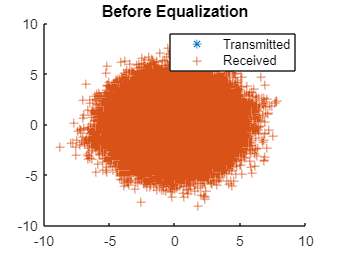


demodsignal= amplified_signalrcv;%IQ_Demodulation(received_signal, fc, fs);

parallel_data=Serial_To_Parallel(demodsignal);
WithoutCP=Remove_Cyclic_Prefix(parallel_data,16);

fftt=FFT_operation(WithoutCP);

freq_e_ZF= Frequency_Equalizer(fftt,'ZF',0,symParallel);     % zero or any value, will not be used
freq_e_W= Frequency_Equalizer(fftt,'W',10,symParallel);

szfft=size(fftt);
rfft=reshape(fftt,[1,szfft(1)*szfft(2)]);
figure;
scatter(real(trans_constellation),imag(trans_constellation),'*');
hold on;
scatter(real(rfft'), imag(rfft'),'+');
legend('Transmitted','Received');
title('Before Equalization');

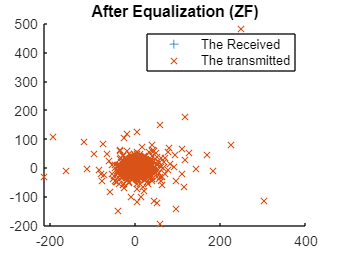


szfreq_e_ZF=size(freq_e_ZF);
rfreq_e_ZF=reshape(freq_e_ZF,[1,szfreq_e_ZF(1)*szfreq_e_ZF(2)]);
figure;
scatter(real(trans_constellation),imag(trans_constellation),'+');
hold on;
scatter(real(rfreq_e_ZF),imag(rfreq_e_ZF),'x');
legend('The Received','The transmitted');
title('After Equalization (ZF)');

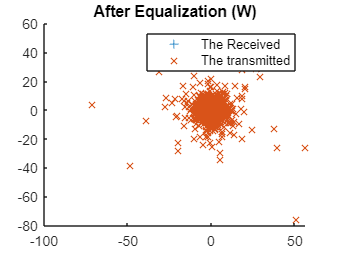


szfreq_e_W=size(freq_e_W);
rfreq_e_W=reshape(freq_e_W,[1,szfreq_e_W(1)*szfreq_e_W(2)]);
figure;
scatter(real(trans_constellation),imag(trans_constellation),'+');
hold on;
scatter(real(rfreq_e_W),imag(rfreq_e_W),'x');
legend('The Received','The transmitted');
title('After Equalization (W)');

figure;
scatter(real(transmitted_signal),imag(transmitted_signal),'*');


**Testing Each Block**

- **Image**

imagepath="C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png";
binary_data=imageToBinary(imagepath);

- **FER**

encoded_data_13 = FEC_Encoding(binary_data, 1/3 , 7);
encoded_data_23 = FEC_Encoding(binary_data, 2/3 , 7);
encoded_data_34 = FEC_Encoding(binary_data, 3/4 , 7);

- **Sympol Mapping**

constellation_test = Symbol_Mapping(encoded_data_23, "BPSK");

- **Serial to Parallel**

SymParallel = Parallel_To_Serial(constellation_test);

- **Nulls**

Whole_Data = AddNullsandPilots(SymParallel);

- **IDFT**

IFFT = Perform_IFFT(Whole_Data);

- **Cyclic prefix**

ofdm_symbol_with_cp = Add_Cyclic_Prefix(IFFT, 16);

- **I/Q Modulation**

modulated_signal = IQ_Modulation(ofdm_symbol_with_cp, 5.2*10^9 , 20*10^6);

- **Amplifing**

amplified_signal=Power_Amplification(modulated_signal,4);
max(abs(amplified_signal)) %less than 40


- **Transmitting**

imagepath="C:\Users\dell\Desktop\Adv_wireless\My_project\lunaluna.png";
code_rate=1/3; % or 2/3 or 3/4
const_len=7;
modulation_type="16QAM"; %BPSK or 16QAM OR 64QAM
cp_length=16;
fc=5.2^10^9;
fs=20*10^6;
gain=4; %6db
transmitted_signal = transmitter(imagepath,code_rate,const_len,modulation_type,cp_length,fc,fs,gain);

%specAn= spectrumAnalyzer('SampleRate', fs, 'Title', 'Magnitude Spectrum of the Baseband Signal');
%spectrumAnalyzer(transpose(specAn));
spec = fftt(transmitted_signal);

n = length(transmitted_signal);          % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(spec).^2/n;    % power of the DFT

plot(f,power)
xlabel('Frequency')
ylabel('Power')

- **Wireless channel without AWGN**

received_signal = simulate_wireless_channel(transmitted_signal);
received_signal = received_signal(1:length(transmitted_signal));
max(abs(received_signal)) %less than 40

- **Wireless channel with AWGN**

SNR_dB = 10;
received_signal_ = simulate_wireless_channel_AWGN(transmitted_signal,SNR_dB);
received_signal = received_signal(1:length(transmitted_signal));
max(abs(received_signal))


- **Low noise amplifing**

amplified_signalrcv = LNA(received_signal, 1.01)
max(abs(amplified_signalrcv)) %less than 40

- **I/Q Demodulation**

demodsignal=IQ_Demodulation(received_signal, fc, fs);

- **Serial to parallel**

parallel_data=Serial_To_Parallel(demodsignal);

- **Removing CP**

WithoutCP=Remove_Cyclic_Prefix(parallel_data,16);

- **FFT**

fftt=FFT_operation(WithoutCP);

- **Frequency Equalizing **

freq_e= Frequency_Equalizer(fftt);

- **ZF equalization**

- **Demapping**

%

- **Parallel to Serial**

%

- **FEC Decoding**

%

**Functions**

- **Importing Image**

function binary_data = imageToBinary(imagepath)
    % img to binary
    image = rgb2gray(imread(imagepath));
    image_normalized = double(image) / 255;
    binary_data = reshape(dec2bin(image_normalized * 255, 8)', 1, []) - '0';
end

- **Forward error correction is applied using convolutional coding with rates 1/3, 2/3, or 3/4 :**

function encoded_data = FEC_Encoding(data, code_rate, const_len)
    % conv encod
    switch code_rate
        case 1/3
            trellis = poly2trellis(const_len, [171 133 133]);
        case 2/3
            trellis = poly2trellis(const_len, [171 133 133]);
        case 3/4
            trellis = poly2trellis(const_len, [171 133 133 133]);
        otherwise
            error('wrong code rate');
    end
    encoded_data = convenc(data, trellis);
end

- **In Symbol Mapping The OFDM subcarriers are modulated using BPSK, QPSK, 16QAM, or 64 QAM depending on the desired rate. The bitstream is divided into groups of size 1, 2, 4 or 6; respectively, and mapped to complex numbers representing the constellation points : **

function constellation = Symbol_Mapping(data_bits, modulation_type)
    % Determine constellation size based on modulation type
    if strcmp(modulation_type, 'BPSK')
        group_size = 1;
        constellation_size=2;
        normalization_factor = 1;
    elseif strcmp(modulation_type, 'QPSK')
        group_size = 2;
        constellation_size=4;
        normalization_factor = 1/sqrt(2);
    elseif strcmp(modulation_type, '16QAM')
        group_size = 4;
        constellation_size=16;
        normalization_factor = 1/sqrt(10);
    elseif strcmp(modulation_type, '64QAM')
        group_size = 6;
        constellation_size=64;
        normalization_factor = 1/sqrt(42);
    else
        error('wrong modulation type');
    end
    % Group data bits based on constellation size
    data_grouped = [];
    group=[];
    for i=1:length(data_bits)
        bit=data_bits(i);
        group=[group bit];
        if mod(i,group_size)==0
            data_grouped=[data_grouped ; group];
            group=[];
        end
    end
    %num_subcarriers=64;
    % Symbol mapping with Gray encoding
    constellation_decimal = bi2de(data_grouped, 'left-msb');
    constellation = qammod(constellation_decimal, constellation_size, 'gray') * normalization_factor;
    figure;
    scatterplot(constellation);
end

- **Serial to Parallel**

function SymParallel = Parallel_To_Serial(data)
    % Convert parallel data to serial
    SymParallel = reshape(data, [48, length(data)/48]);
end

- **Nulls**

function Whole_Data = AddNullsandPilots(SymParallel)
    PilotsI = [8,22,44,58];
    sz=size(SymParallel);
    nullsubcar = zeros(1,sz(2));
    Whole_Data = [nullsubcar; SymParallel(1:6,:);nullsubcar;....
        SymParallel(7:19,:);nullsubcar;SymParallel(20:24,:);...
        repmat(nullsubcar,11,1);SymParallel(25:29,:);nullsubcar;...
        SymParallel(30:42,:);nullsubcar;SymParallel(43:48,:)];
    pilots = [1,1,1,-1];

    for i = 1:2:length(SymParallel)
        Whole_Data(PilotsI,i)=pilots;
    end

    
end

- **IDFT**

function IFFT = Perform_IFFT(Whole_Data)   % Perform IFFT
    IFFT = ifft(Whole_Data,64);
end

- **Add Cyclic prefix to the data stream**

function result = Add_Cyclic_Prefix(ofdm_symbol, cp_length)
    % Add cyclic prefix
    ofdm_symbol_with_cp = [ofdm_symbol(end-cp_length+1:end,:);ofdm_symbol];
    %parallel to serial
    result=[];
    sz=size(ofdm_symbol_with_cp);
    for i=1:sz(1)
        result=[result, ofdm_symbol_with_cp(i,:)];
    end
end

- **I/Q Modulation**

function modulated_signal = IQ_Modulation(ofdm_symbol_with_cp, fc, fs)
    % Create time vector
    t = (0:1/fs:(1/fs)*(length(ofdm_symbol_with_cp)-1));%(0:length(ofdm_symbol_with_cp)-1) / fs;
    I = real(ofdm_symbol_with_cp) .* cos(2*pi*fc*t);
    Q = imag(ofdm_symbol_with_cp) .* sin(2*pi*fc*t);
    % Combine I/Q components
    modulated_signal = I + Q;
end

- **Amplifing**

function amplified_signal = Power_Amplification(signal, gain)
    amplified_signal = signal * gain;
end


- **Implementaion of the transmitter**

function [transmitted_signal,constellation,ofdm_symbol_with_cp,Whole_Data] = transmitter(imagepath,code_rate,const_len,modulation_type,cp_length,fc,fs,gain)
    binary_data = imageToBinary(imagepath);
    encoded_data = FEC_Encoding(binary_data, code_rate, const_len);
    constellation = Symbol_Mapping(encoded_data, modulation_type);% Symbol mapping
    SymParallel = Parallel_To_Serial(constellation);
    Whole_Data = AddNullsandPilots(SymParallel);
    IFFT = Perform_IFFT(Whole_Data);
    ofdm_symbol_with_cp = Add_Cyclic_Prefix(IFFT, cp_length);
    modulated_signal = IQ_Modulation(ofdm_symbol_with_cp, fc, fs);
    transmitted_signal = Power_Amplification(modulated_signal, gain);
end

### 2)Simultion of Wireless Channel

- **Wireless channel simulation (without AWGN)**

function received_signal = simulate_wireless_channel(transmitted_signal)
    % Define the FIR filter coefficients
    h = [0.8208+0.2052j; 0.4104+0.1026j; 0.2052+0.2052j; 0.1026+0.1026j];
    % Convolve transmitted signal with FIR filter
    received_signal = conv(transmitted_signal, h);
end

- **with AWGN**

function received_signal = simulate_wireless_channel_AWGN(transmitted_signal,SNR_dB)
    h = [0.8208+0.2052j; 0.4104+0.1026j; 0.2052+0.2052j; 0.1026+0.1026j];
    % Convolve transmitted signal with FIR filter
    received_signal = conv(transmitted_signal, h);
    
    % AWGN parameters
    SNR = 10^(SNR_dB/10);  % Convert SNR to linear scale
    % Generate complex Gaussian noise with the same length as the received signal
    noise = sqrt(0.5/SNR) * (randn(size(received_signal)) + 1i*randn(size(received_signal)));

    % Add noise to the received signal
    received_signal = received_signal + noise;
end


### 3)Receiver part Functionallities && employing 

- **Low noise amplifier**

function amplified_signalrcv = LNA(received_signal, gain)
    amplified_signalrcv = received_signal * gain;
end

- **I/Q Demodulation**

function Demodulated = IQ_Demodulation(received_signal, fc, fs)
    % Create time vector
    t = (0:1/fs:(1/fs)*(length(received_signal)-1));%(0:length(received_signal)-1) / fs;
    % Demodulate in-phase (I) and quadrature (Q) components
    I = received_signal .* cos(2*pi*fc*t);
    Q = -received_signal .* sin(2*pi*fc*t);
    Demodulated=I+(1j*Q);
end

- **Serial to parallel**

function parallel_data = Serial_To_Parallel(serial_data)
    % Convert serial data to parallel
    parallel_data = reshape(serial_data, [], 80)';
end

- **Removing CP**

function WithoutCP = Remove_Cyclic_Prefix(ofdm_symbol_with_cp, cp_length)
    % Remove cyclic prefix
    WithoutCP = ofdm_symbol_with_cp(cp_length+1:end,:);
end

- **FFT**

function frequency_domain_data = FFT_operation(parallel_data)
    % Perform FFT
    frequency_domain_data = fft(parallel_data, 64);
end

- **Channel Estimation**

function interpTime = interpolate(PilotsIndc,gg,r,c)
interpFreq = zeros(r, c);
interpTime = zeros(r, c);
for o = 1 :2: c
f_real = fit(PilotsIndc',gg(:,ceil(o/2)),'cubicinterp');
interpFreq(:,o) = f_real(1:r);
end
for u = 1 : r
    f_imag = fit([1:2:c]',interpFreq(u,1:2:end)','cubicinterp');
    interpTime(u,:) = f_imag(1:c);
end
end

- **Frequency Equalizing **

function equalized_data = Frequency_Equalizer(fft,equalization_type,SNR,SymParallel)
    PilotsI = [8,22,44,58];
    G = fft(PilotsI,1:2:end) ./ SymParallel(PilotsI,1:2:end);  
    sz=size(fft);
    n = sz(1)*sz(2);
    interpolation_T_Real = interpolate(PilotsI, real(G), 64, n/64);
    interpolation_T_Imag = interpolate(PilotsI, imag(G), 64, n/64);
    estimatedChannel = interpolation_T_Real + 1i * interpolation_T_Imag;

    % zero-forcing
    ZF = fft./estimatedChannel;

    %equalized_data = ZF;

    % Wiener
    % multiplies the received signal by a filter coefficient that depends on both the channel frequency response and the SNR
    snr = 18;     %% remove later
    estimatedChannel_conj = conj(estimatedChannel);
    w_1 = estimatedChannel_conj .*fft;
    w_2 = 1/SNR + (abs(estimatedChannel).^2 .* fft);
    W = w_1 ./ w_2;   
    %equalized_data =W;

    if equalization_type == "ZF"
        equalized_data = ZF;
    elseif equalization_type == "W"
        equalized_data = W;
    else 
        error('Invalid equalization method')
    end


end

- **Demapping**

function demapped_bits = Symbol_Demapping(constellation, modulation_type)
    % Determine constellation size based on modulation type
    if strcmp(modulation_type, 'BPSK')
        group_size = 1;
        constellation_size=2;
        normalization_factor = 1;
    elseif strcmp(modulation_type, 'QPSK')
        group_size = 2;
        constellation_size=4;
        normalization_factor = 1/sqrt(2);
    elseif strcmp(modulation_type, '16QAM')
        group_size = 4;
        constellation_size=16;
        normalization_factor = 1/sqrt(10);
    elseif strcmp(modulation_type, '64QAM')
        group_size = 6;
        constellation_size=64;
        normalization_factor = 1/sqrt(42);
    else
        error('Invalid modulation type');
    end
    demapped_symbols = qamdemod(constellation / normalization_factor, constellation_size, 'gray')* (1/normalization_factor);
    demapped_data_bits = de2bi(demapped_symbols, log2(constellation_size), 'left-msb');
end


- **Parallel to Serial**

function serial_data = Parallel_to_Serial(parallel_data)
    % Convert parallel data to serial
end

- **FEC Decoding**

function decoded_data_bits = FEC_Decoding(received_data_bits, code_rate)
    % Define convolutional coding parameters based on code rate
    if code_rate == 1/3
        trellis = poly2trellis(const_len, [171 133 133]);
    elseif code_rate == 2/3
        trellis = poly2trellis(const_len, [171 133 133]);
    elseif code_rate == 3/4
        trellis = poly2trellis(const_len, [171 133 133 133]);
    else
        error('Invalid code rate');
    end
    % Convolutional decoding
    decoded_data_bits = vitdec(received_data_bits, trellis, 100, 'trunc', 'hard');
end